clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/archive_scripts');

% Analysis parameters
min_stroke_age = 0; % Minimum stroke onset age (years)
min_test_age = 0; % Minimum age at PSOM (years)
min_test_interval = 0.5; % Minimum interval between onset and assessment (years)
min_freq = 1; % Minimum lesion frequency
pos_only = 1; % Use only positive model weights for predictions
get_vips_preds = 1; % load test fold predictions for pediatric models when generating adult model predictions

% Path to adult SM model
sm_col = "gpb_dif";
sm_outcome = "contra_motor";    
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir); 

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Get predicted pediatric scores (SM)
[cfg_sm, beh_csv] = load_and_format_vips_lesions(sm_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


if pos_only == 1
    [~, ui_pred_sm, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
        sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
else
    [ui_pred_sm, ~, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
        sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
end

    "Applying model for "    "gpb_dif"




% Get predicted pediatric scores (lang)
[cfg_lang, beh_csv] =  load_and_format_vips_lesions(lang_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


if pos_only == 1
    [~, ui_pred_lang, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
        lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
else
    [ui_pred_lang, ~, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
        lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);
end

    "Applying model for "    "mae_token"



% Get indices of patients that meet inclusion criteria
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval],2));

% Subset dataset and predictions to retain only included patients
beh_csv = beh_csv(inc_ind,:);
ui_pred_sm = ui_pred_sm(inc_ind);
ui_pred_lang = ui_pred_lang(inc_ind);
disp(['N=' num2str(length(inc_ind)) ' included pediatric patients'])

N=469 included pediatric patients


% Define standardized covariates
covs = zscore([beh_csv.lh_vol, beh_csv.rh_vol, beh_csv.stroke_age, beh_csv.yrs2test]);

% Do predicted scores correlate with observed pediatric scores?

% Get correlations
[r_pred_sm, p_pred_sm] = corr(ui_pred_sm, beh_csv.(sm_outcome), 'type', 'Spearman', 'rows', 'pairwise')

r_pred_sm = single
       0.4322897


p_pred_sm = single
    8.894862e-23


[r_pred_lang, p_pred_lang] = corr(ui_pred_lang, beh_csv.(lang_outcome), 'type', 'Spearman', 'rows', 'pairwise')

r_pred_lang = single
       0.4185907


p_pred_lang = single
    2.547862e-21


% Get CIs
bootfun = @(IV,DV) corr(IV, DV, "Type", "spearman", "rows", "pairwise");
ci_pred_sm = bootci(1000,{bootfun,ui_pred_sm, beh_csv.(sm_outcome)}, "type", "normal")

ci_pred_sm = 2×1 single column vector
       0.3575899
       0.5124462


ci_pred_lang = bootci(1000,{bootfun,ui_pred_lang, beh_csv.(lang_outcome)}, "type", "normal")

ci_pred_lang = 2×1 single column vector
       0.3409126
       0.4968767


% get partial correlations
[pr_pred_sm, pp_pred_sm] = partialcorr(ui_pred_sm, beh_csv.(sm_outcome), covs, 'type', 'Spearman', 'rows', 'pairwise')

pr_pred_sm = single
       0.3250336


pp_pred_sm = single
    6.664291e-13


[pr_pred_lang, pp_pred_lang] = partialcorr(ui_pred_lang, beh_csv.(lang_outcome), covs, 'type', 'Spearman', 'rows', 'pairwise')

pr_pred_lang = single
        0.250141


pp_pred_lang = single
    4.586735e-08


% Get CIs
bootfun = @(IV,DV, covariates) partialcorr(IV, DV, covariates, "Type", "spearman", "rows", "pairwise");
ci_pred_pr_sm = bootci(1000, {bootfun, ui_pred_sm, beh_csv.(sm_outcome), covs}, "type", "normal")

ci_pred_pr_sm = 2×1 single column vector
        0.238307
       0.4154881


ci_pred_pr_lang = bootci(1000, {bootfun, ui_pred_lang, beh_csv.(lang_outcome), covs}, "type", "normal")

ci_pred_pr_lang = 2×1 single column vector
       0.1673604
       0.3275072


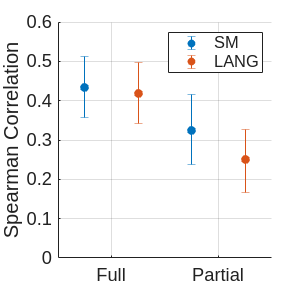

% Plot correlation results
clf;
errorbar(0.75, r_pred_sm, r_pred_sm-ci_pred_sm(1), ci_pred_sm(2)-r_pred_sm, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar(1.25, r_pred_lang, r_pred_lang-ci_pred_lang(1), ci_pred_lang(2)-r_pred_lang, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
errorbar(1.75, pr_pred_sm, pr_pred_sm-ci_pred_pr_sm(1), ci_pred_pr_sm(2)-pr_pred_sm, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
errorbar(2.25, pr_pred_lang, pr_pred_lang-ci_pred_pr_lang(1), ci_pred_pr_lang(2)-pr_pred_lang, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
ylim([0, 0.6]);
xlim([0.5, 2.5])
set(gca, 'Xtick', [1:1:2]);
set(gca, 'XtickLabel', {'Full', 'Partial'});
ylabel('Spearman Correlation');
legend({'SM', 'LANG'}); box off;
grid on; set(gcf, 'position', [0, 0, 300, 290]); set(gca, 'FontSize', 14); title(''); 

% Can adult model predictions be used to classify pediatric impairment status?

% ROC AUC analysis (SM)
roc_pred_sm = rocmetrics(beh_csv.(sm_outcome) > 0.5, ui_pred_sm, 1, 'NumBootstraps', 1000); 
perm_Y = beh_csv.(sm_outcome) > 0.5;
perm_auc = zeros(1000,1);
for i = 1:1000 % Permutation test
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, ui_pred_sm, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_sm = (numel(find(perm_auc > roc_pred_sm.auc))+1)./1001    

perm_p_sm =       0.000999000999000999


[a1, l1, u1] = auc(roc_pred_sm)

a1 = single
       0.7580785


l1 = single
         0.70015


u1 = single
       0.8067791


% AUC on residuals (SM)
mdl = fitlm(covs, ui_pred_sm);
roc_pred_sm_pr = rocmetrics(beh_csv.(sm_outcome) > 0.5, mdl.Residuals.Standardized, 1, 'NumBootstraps', 1000);
perm_Y = beh_csv.(sm_outcome) > 0.5;
perm_auc = zeros(1000,1);
for i = 1:1000 % Permutation test
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, mdl.Residuals.Standardized, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_sm_pr = (numel(find(perm_auc > roc_pred_sm_pr.auc))+1)./1001    

perm_p_sm_pr =       0.000999000999000999


roc_pred_sm_pr.AUC

ans = 3×1 single column vector
        0.648693
       0.5883681
       0.7077826


% ROC AUC analysis (Lang)
roc_pred_lang = rocmetrics(beh_csv.(lang_outcome) > 0.5, ui_pred_lang, 1, 'NumBootstraps', 1000); 
perm_Y = beh_csv.(lang_outcome) > 0.5;
perm_auc = zeros(1000,1);
for i = 1:1000 % Permutation test
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, ui_pred_lang, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_lang = (numel(find(perm_auc > roc_pred_lang.auc))+1)./1001

perm_p_lang =       0.000999000999000999


[a2, l2, u2] = auc(roc_pred_lang)

a2 = single
        0.756175


l2 = single
       0.6847864


u2 = single
       0.8099918


% AUC on residuals (Lang)
mdl = fitlm(covs, ui_pred_lang);
roc_pred_lang_pr = rocmetrics(beh_csv.(lang_outcome) > 0.5, mdl.Residuals.Standardized, 1, 'NumBootstraps', 1000);
perm_Y = beh_csv.(lang_outcome) > 0.5;
perm_auc = zeros(1000,1); % Permutation test
for i = 1:1000
    perm_Yi = perm_Y(randperm(length(perm_Y)));
    roc_perm = rocmetrics(perm_Yi > 0.5, mdl.Residuals.Standardized, 1);
    perm_auc(i,1) = roc_perm.auc;
end
perm_p_lang_pr = (numel(find(perm_auc > roc_pred_lang_pr.auc))+1)./1001    

perm_p_lang_pr =       0.000999000999000999


roc_pred_lang_pr.AUC

ans = 3×1 single column vector
       0.6334589
       0.5432864
       0.7108314


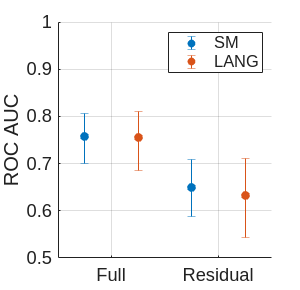

% Plot classification results
clf;
errorbar(0.75, roc_pred_sm.AUC(1), roc_pred_sm.AUC(1)-roc_pred_sm.AUC(2), roc_pred_sm.AUC(3)-roc_pred_sm.AUC(1), 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar(1.25, roc_pred_lang.AUC(1), roc_pred_lang.AUC(1)-roc_pred_lang.AUC(2), roc_pred_lang.AUC(3)-roc_pred_lang.AUC(1), 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
errorbar(1.75, roc_pred_sm_pr.AUC(1), roc_pred_sm_pr.AUC(1)-roc_pred_sm_pr.AUC(2), roc_pred_sm_pr.AUC(3)-roc_pred_sm_pr.AUC(1), 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
errorbar(2.25, roc_pred_lang_pr.AUC(1), roc_pred_lang_pr.AUC(1)-roc_pred_lang_pr.AUC(2), roc_pred_lang_pr.AUC(3)-roc_pred_lang_pr.AUC(1), 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
ylim([0.5, 1]);
xlim([0.5 2.5]);
set(gca, 'Xtick', [1:1:2]);
set(gca, 'XtickLabel', {'Full', 'Residual'});
ylabel('ROC AUC');
legend({'SM', 'LANG'}); box off;
grid on; set(gcf, 'position', [0, 0, 300, 290]); set(gca, 'FontSize', 14); title(''); 

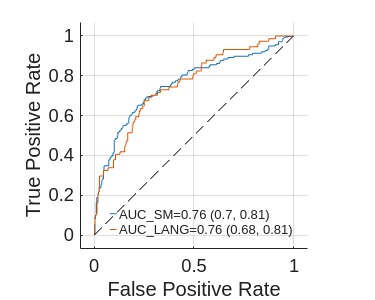


% Plot ROC curves
clf;
plot(roc_pred_sm, 'ShowModelOperatingPoint', false);
hold on;
plot(roc_pred_lang, 'ShowModelOperatingPoint', false);
lgd = legend({['AUC_SM=' num2str(round(a1,2)) ' (' num2str(round(l1,2)) ', ' num2str(round(u1,2)) ')']...
    ['AUC_LANG=' num2str(round(a2,2)) ' (' num2str(round(l2,2)) ', ' num2str(round(u2,2)) ')']}, 'FontSize', 10);
lgd.IconColumnWidth = 5;
legend('box', 'off')
grid on; set(gcf, 'position', [0, 0, 375, 300]); set(gca, 'FontSize', 14); title('');

% Fit ordinal logistic regression models to estimate aOR and compare against base models

% Reverse code and re-code categories to set reference category to unimpaired (SM outcome)
Y1 = zeros(length(inc_ind),1);
Y1(beh_csv.(sm_outcome)==0)=3;
Y1(beh_csv.(sm_outcome)==0.5)=2;
Y1(beh_csv.(sm_outcome)==1)=1;
Y1(beh_csv.(sm_outcome)==2)=0;
Y1 = categorical(Y1);

% Reverse code and re-code categories to set reference category to unimpaired (LANG outcome)
Y2 = zeros(length(inc_ind),1);
Y2(beh_csv.(lang_outcome)==0)=3;
Y2(beh_csv.(lang_outcome)==0.5)=2;
Y2(beh_csv.(lang_outcome)==1)=1;
Y2(beh_csv.(lang_outcome)==2)=0;
Y2 = categorical(Y2); 

% Fit base OLR models
mdl1a = fitmnr(covs, Y1, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % SM Model
mdl2a = fitmnr(covs, Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % LANG Model   

% Add adult predictions (SM)
mdl1b = fitmnr([covs, zscore(ui_pred_sm)], Y1, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl1b = Multinomial regression with ordinal responses

                       Value           SE          tStat         pValue   
                     __________    __________    __________    ___________

    (Intercept_0)     -2.674516     0.1831212     -14.60517              0
    (Intercept_1)    -0.9966322     0.1121265     -8.888463    6.19601e-19
    (Intercept_2)      0.205969    0.09963334       2.06727     0.03870872
    LH Volume        -0.1359899     0.1439711    -0.9445635      0.3448818
    RH Volume         -0.372332     0.1550797     -2.400908     0.01635446
    Age at Stroke    -0.2126815    0.09246759     -2.300065     0.02144454
    Time to Test     0.09281991    0.08925741      1.039913      0.2983805
    Ad

% Add adult predictions (Lang)
mdl2b = fitmnr([covs, zscore(ui_pred_lang)], Y2, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl2b = Multinomial regression with ordinal responses

                       Value           SE          tStat         pValue   
                     __________    __________    _________    ____________

    (Intercept_0)     -3.068491      0.213499    -14.37239               0
    (Intercept_1)     -1.949397     0.1459686     -13.3549    1.109016e-40
    (Intercept_2)     -1.096194     0.1151148    -9.522611    1.688825e-21
    LH Volume        -0.4063142     0.2936619    -1.383613       0.1664771
    RH Volume         0.2983866    0.09084434     3.284592     0.001021303
    Age at Stroke    -0.2993132     0.1148432    -2.606278     0.009153223
    Time to Test      0.1541805     0.1047083     1.472477        0.140892
    Ad

% Get coeffs and CIs
mdl1b_ci = coefCI(mdl1b); mdl1b_ci = exp(mdl1b_ci(4:end,:));
mdl2b_ci = coefCI(mdl2b); mdl2b_ci = exp(mdl2b_ci(4:end,:));
mdl1b_coef = exp(mdl1b.Coefficients.Value(4:end));
mdl2b_coef = exp(mdl2b.Coefficients.Value(4:end));

% Likelihood ratio tests of expanded vs. base models
p_llr_sm = 1-chi2cdf(-2*(mdl1a.LogLikelihood-mdl1b.LogLikelihood),1) % SM 

p_llr_sm = single
     0


p_llr_lang = 1-chi2cdf(-2*(mdl2a.LogLikelihood-mdl2b.LogLikelihood),1) % Lang

p_llr_lang = single
    0.0001696348


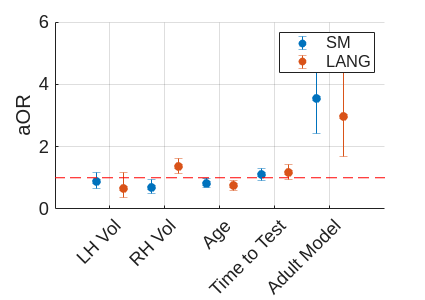

% Plot aORs and 95% CIs
clf;
errorbar([0.75,1.75,2.75,3.75,4.75], mdl1b_coef, mdl1b_coef-mdl1b_ci(:,1), mdl1b_ci(:,2)-mdl1b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar([1.25,2.25,3.25,4.25, 5.25], mdl2b_coef, mdl2b_coef-mdl2b_ci(:,1), mdl2b_ci(:,2)-mdl2b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
line([0, 6], [1, 1], 'LineStyle', '--', 'Color', 'r', 'LineWidth', 0.5);
ylabel('aOR'); grid on; legend({'SM', 'LANG'});
set(gca, 'Xtick', 1:1:5);
set(gca, 'XtickLabel', {'LH Vol', 'RH Vol', 'Age', 'Time to Test', 'Adult Model'});
set(gca, 'XtickLabelRotation', 45);
set(gca, 'FontSize', 14);
set(gcf, 'color', 'w');
set(gcf, 'position', [0, 0, 425, 300]); box off;

% Compare cross-validation models (LANG)
clf;

% Add path to functions
addpath(genpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/archive_scripts'));

% Analysis inputs
model_spec = 'logistic_ridge';
if pos_only == 1
    modalities = {'base', 'expanded_pos' 'expanded_vips_pos'}; % use only positive model weights to generate pediatric predictions
else
    modalities = {'base', 'expanded_full' 'expanded_vips_full'}; % use full model weights to generate pediatric predictions
end    
beh_col = 'worst_lang';
min_freq_stack = 1;

% Fit base and expanded models
for i = 1:length(modalities)
    cv_models{i,1} = run_vips_psom_models_cv2(lang_model_path, modalities{i}, model_spec, beh_col, min_stroke_age, min_test_age, min_test_interval,...
        min_freq, min_freq_stack, 0, pos_only);   
    load(fullfile(cv_models{i,1}, 'cv_results.mat'));
    results.(modalities{i}) = cv_results;
    clear cv_results
end

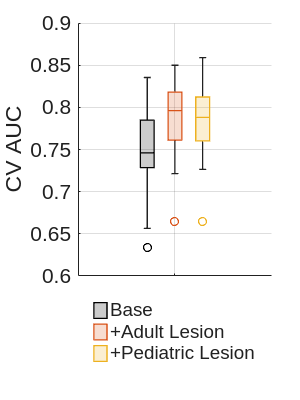

% Plot CV results (LANG)
clf;
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    plot_results(:,j) = results.(modalities{j}).roc_auc(:);
end
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
b(2).BoxFaceColor = [0.85, 0.325, 0.098];
b(2).MarkerColor = [0.85, 0.325, 0.098];
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l = legend({'Base', '+Adult Lesion', '+Pediatric Lesion'}, 'Location', 'southoutside');
l.IconColumnWidth = 10;
l.Box = "off";
ylim([0.6, 0.9]);
set(gca, 'XtickLabel', '');
ylabel('CV AUC'); grid on; 
title(''); set(gca, 'FontSize', 16); 
set(gcf, 'position', [0, 0, 300, 400]); 
box off; 

% Compare CV results (Lang)
[~, p_lang_avb, ci_lang_avb, stats_lang_avb] = ttest(plot_results(:,2), plot_results(:,1))

p_lang_avb =       4.30189615473196e-07


ci_lang_avb =         0.0259868509102819
         0.048361546344662


stats_lang_avb = struct with fields:
    tstat: 6.85808441968984
       df: 24
       sd: 0.0271024650270732


[~, p_lang_avp, ci_lang_avp, stats_lang_avp] = ttest(plot_results(:,2), plot_results(:,3))

p_lang_avp =          0.287552480489209


ci_lang_avp =        -0.0016988542260612
       0.00548427845854411


stats_lang_avp = struct with fields:
    tstat: 1.0876496330518
       df: 24
       sd: 0.00870092748034474


[~, p_lang_bvp, ci_lang_bvp, stats_lang_bvp] = ttest(plot_results(:,3), plot_results(:,1))

p_lang_bvp =         1.973633017949e-06


ci_lang_bvp =          0.023580359097832
        0.0469826139246289


stats_lang_bvp = struct with fields:
    tstat: 6.22311053371209
       df: 24
       sd: 0.0283471475559547


% Compare cross-validation models (SM)

% Clear variables
clear cv_models cv_results results plot_results group

% Analysis inputs
model_spec = 'logistic_ridge';
if pos_only == 1
    modalities = {'base', 'expanded_pos' 'expanded_vips_pos'}; % use only positive model weights to generate pediatric predictions
else
    modalities = {'base', 'expanded_full' 'expanded_vips_full'}; % use full model weights to generate pediatric predictions
end    
beh_col = 'contra_motor';
min_freq_stack = 1;

% Fit base and expanded models
for i = 1:length(modalities)
    cv_models{i,1} = run_vips_psom_models_cv2(sm_model_path, modalities{i}, model_spec, beh_col, min_stroke_age, min_test_age, min_test_interval,...
        min_freq, min_freq_stack, 0, pos_only);   
    load(fullfile(cv_models{i,1}, 'cv_results.mat'));
    results.(modalities{i}) = cv_results;
    clear cv_results
end

% Plot CV results (SM)
clf;
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    plot_results(:,j) = results.(modalities{j}).roc_auc(:);
end
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
b(2).BoxFaceColor = b(1).BoxFaceColor;
b(2).MarkerColor = b(1).MarkerColor;
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l = legend({'Base', '+Adult Lesion', '+Pediatric Lesion'}, 'Location', 'southoutside');
l.IconColumnWidth = 10

l =   Legend (Base, +Adult Lesion, +Pediatric Lesion) with properties:

         String: {'Base'  '+Adult Lesion'  '+Pediatric Lesion'}
       Location: 'southoutside'
    Orientation: 'vertical'
       FontSize: 8.55
       Position: [0.333240751155785 0.0902916471535961 0.366851838429769 0.10250000094374]
          Units: 'normalized'

  Show all properties


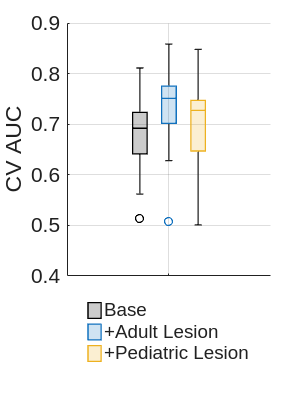

l.Box = "off";
ylim([0.4, 0.9]);
set(gca, 'XtickLabel', '');
ylabel('CV AUC'); grid on; 
title(''); set(gca, 'FontSize', 16); 

set(gcf, 'position', [0, 0, 300, 400]); 

% Compare CV results (SM)
[~, p_sm_avb, ci_sm_avb, stats_sm_avb] = ttest(plot_results(:,2), plot_results(:,1))

p_sm_avb =       6.04102150958086e-08


ci_sm_avb =         0.0377199973750304
        0.0653010664295961


stats_sm_avb = struct with fields:
    tstat: 7.70909296456587
       df: 24
       sd: 0.0334089445665506


[~, p_sm_avp, ci_sm_avp, stats_sm_avp] = ttest(plot_results(:,2), plot_results(:,3))

p_sm_avp =       5.80306271595081e-07


ci_sm_avp =         0.0227054529305416
        0.0427840585593266


stats_sm_avp = struct with fields:
    tstat: 6.73172784328651
       df: 24
       sd: 0.0243212118101225


[~, p_sm_bvp, ci_sm_bvp, stats_sm_bvp] = ttest(plot_results(:,3), plot_results(:,1))

p_sm_bvp =        0.00559173636947557


ci_sm_bvp =        0.00604113131548756
        0.0314904209992707


stats_sm_bvp = struct with fields:
    tstat: 3.0437516253138
       df: 24
       sd: 0.0308267205531997


% Get FWE corrected p-values
p_pred = [p_pred_sm, p_pred_lang, pp_pred_sm, pp_pred_lang, perm_p_sm, perm_p_lang, perm_p_sm_pr, perm_p_lang_pr,...
    p_llr_sm, p_llr_lang,  mdl1b.Coefficients.pValue(end)', mdl2b.Coefficients.pValue(end)'];
pfwe_pred = bonf_holm(p_pred);
disp(pfwe_pred);

    9.784348e-22    2.547862e-20    5.997862e-12    3.210715e-07     0.003996004     0.003996004     0.002997003     0.001998002               0     0.001017809    3.983656e-10     0.001068683



p_cv = [p_lang_avb, p_lang_avp, p_lang_bvp, p_sm_avb, p_sm_avp, p_sm_bvp];
pfwe_cv = bonf_holm(p_cv);
disp(pfwe_cv);

      2.15094807736598e-06         0.287552480489209      5.92089905384699e-06      3.62461290574852e-07      2.32122508638032e-06        0.0111834727389511



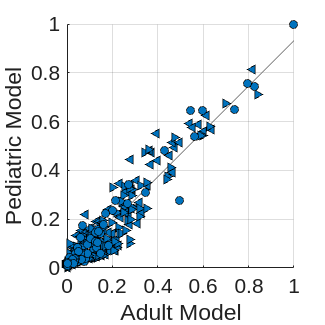

% How do adult vs. pediatric model predictions relate?

% Rescale predictions from adult and pediatric models to have range [0, 1]
ui_pred_sm_rescale = normalize(ui_pred_sm,'range', [0,1]);
ui_pred_lang_rescale = normalize(ui_pred_lang, 'range', [0,1]);
vips_pred_sm_rescale = normalize(vips_pred_sm, 'range', [0,1]);
vips_pred_lang_rescale = normalize(vips_pred_lang, 'range', [0,1]);

% Plot adult vs. pediatric predictions (SM)
clf;
scatter(ui_pred_sm_rescale,vips_pred_sm_rescale,1, 'Marker', '.', 'MarkerEdgeColor', [0.85, 0.325, 0.098])
lsline; hold on;
scatter(ui_pred_sm_rescale(string(beh_csv.laterality) == 'L'),vips_pred_sm_rescale(string(beh_csv.laterality) == 'L'), 'Marker', '<', 'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor',  [0, 0.447, 0.741])
hold on
scatter((ui_pred_sm_rescale(string(beh_csv.laterality) == 'R')),(vips_pred_sm_rescale(string(beh_csv.laterality) == 'R')), 'Marker', '>',  'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor', [0, 0.447, 0.741])
hold on
scatter(ui_pred_sm_rescale(string(beh_csv.laterality) == 'B'),vips_pred_sm_rescale(string(beh_csv.laterality) == 'B'), 'Marker', 'o',  'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor',  [0, 0.447, 0.741])
ylabel('Pediatric Model');
xlabel('Adult Model');
axis('tight')
grid on;set(gca, 'Xtick', 0:0.2:1)
set(gcf, 'position', [0, 0, 325, 325]); set(gca, 'FontSize', 16); title(''); 

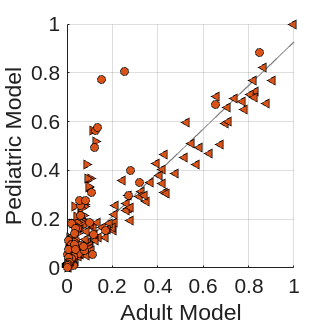


% Plot full sample (LANG)
clf;
scatter(ui_pred_lang_rescale,vips_pred_lang_rescale,1, 'Marker', '.', 'MarkerEdgeColor', [0.85, 0.325, 0.098])
lsline; hold on;
scatter(ui_pred_lang_rescale(string(beh_csv.laterality) == 'L'),vips_pred_lang_rescale(string(beh_csv.laterality) == 'L'), 'Marker', '<', 'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor',  [0.85, 0.325, 0.098])
hold on
scatter((ui_pred_lang_rescale(string(beh_csv.laterality) == 'R')),(vips_pred_lang_rescale(string(beh_csv.laterality) == 'R')),'Marker', '>',  'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor',  [0.85, 0.325, 0.098])
hold on
scatter(ui_pred_lang_rescale(string(beh_csv.laterality) == 'B'),vips_pred_lang_rescale(string(beh_csv.laterality) == 'B'),'Marker', 'o',  'MarkerEdgeColor', [0 0 0], 'MarkerFaceColor',  [0.85, 0.325, 0.098])
ylabel('Pediatric Model');
xlabel('Adult Model');
axis('tight')
grid on;
set(gca, 'Xtick', 0:0.2:1)
set(gcf, 'position', [0, 0, 325, 325]); set(gca, 'FontSize', 16); title(''); 

% Are predictions more similar for domain-matched vs. domain-mismatched models when accounting for lesion size?

% Z-test on partial correlations for LANG
pr12l = partialcorr(ui_pred_lang_rescale, vips_pred_lang_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr12l = single
       0.8329895


pr13l = partialcorr(ui_pred_sm_rescale, vips_pred_lang_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr13l = single
       0.4622569


pr23l = partialcorr(ui_pred_sm_rescale, ui_pred_lang_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr23l = single
       0.3684217


[zstatl, pvall, dfl] = steiger_z(pr12l, pr13l, pr23l, 469)

zstatl = single
        11.48481


pvall = single
     0


dfl =    466


% Z-test on partial correlations for SM
pr12s = partialcorr(ui_pred_sm_rescale, vips_pred_sm_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr12s = single
       0.7559513


pr13s = partialcorr(ui_pred_lang_rescale, vips_pred_sm_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr13s = single
       0.6361293


pr23s = partialcorr(ui_pred_sm_rescale, ui_pred_lang_rescale, [zscore(beh_csv.lh_vol), zscore(beh_csv.rh_vol)])

pr23s = single
       0.3684217


[zstats, pvals, dfs] = steiger_z(pr12s, pr13s, pr23s, 469)

zstats = single
        3.862472


pvals = single
    0.0001122952


dfs =    466


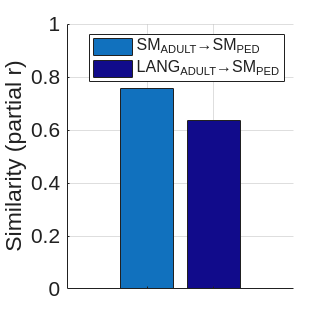

% Plot same vs. other domain

% SM
clf;
b1 = bar(0.5, pr12s);
hold on
b2 = bar(1.5, pr13s);
set(gca, 'Xtick', 0.5:1:1.5);
b2.FaceColor = 'flat';
b2.CData(1,:) = b1(1).CData(1,:)-[0, 0.4, 0.2];
grid on;
set(gca, 'XtickLabel', '');
ylabel('Similarity (partial r)')
set(gca, 'FontSize', 16);
legend({['SM_A_D_U_L_T' char(8594) 'SM_P_E_D'], ['LANG_A_D_U_L_T' char(8594) 'SM_P_E_D']}, 'FontSize', 12); 
set(gcf, 'position',  [0, 0, 325, 325]); ylim([0,1]);box off;

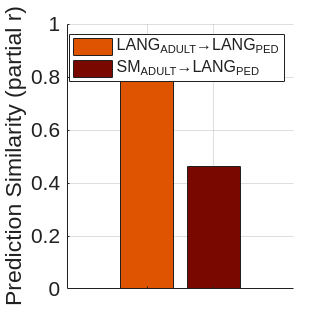


% LANG
clf;
b3 = bar(0.5, pr12l);
hold on
b4 = bar(1.5, pr13l);
set(gca, 'Xtick', 0.5:1:1.5);
b3.FaceColor = 'flat';
b4.FaceColor = 'flat';
b3.CData(1,:) = [0.87, 0.33, 0];
b4.CData(1,:) = b3(1).CData(1,:)-[0.4, 0.3, 0];
grid on;
set(gca, 'XtickLabel', '');
ylabel('Prediction Similarity (partial r)')
set(gca, 'FontSize', 16);
legend({['LANG_A_D_U_L_T' char(8594) 'LANG_P_E_D'], ['SM_A_D_U_L_T' char(8594) 'LANG_P_E_D']}, 'FontSize', 12); 
set(gcf, 'position',  [0, 0, 325, 325]); ylim([0,1]);box off;

% Hemisphere analysis for LANG

% Partial correlations for LANG LH
pr12 = partialcorr(ui_pred_lang_rescale(string(beh_csv.laterality)=='L'), vips_pred_lang_rescale(string(beh_csv.laterality)=='L'), beh_csv.lh_vol(string(beh_csv.laterality)=='L'))

pr12 = single
        0.852241


pr13 = partialcorr(ui_pred_sm_rescale(string(beh_csv.laterality)=='L'), vips_pred_lang_rescale(string(beh_csv.laterality)=='L'), beh_csv.lh_vol(string(beh_csv.laterality)=='L'))

pr13 = single
       0.3673716


pr23 = partialcorr(ui_pred_sm_rescale(string(beh_csv.laterality)=='L'), ui_pred_lang_rescale(string(beh_csv.laterality)=='L'), beh_csv.lh_vol(string(beh_csv.laterality)=='L'))

pr23 = single
       0.2001565


[zstat, pval, df] = steiger_z(pr12, pr13, pr23, 180)

zstat = single
        8.366061


pval = single
     0


df =    177


% Partial correlations for LANG RH
pr12 = partialcorr(ui_pred_lang_rescale(string(beh_csv.laterality)=='R'), vips_pred_lang_rescale(string(beh_csv.laterality)=='R'), beh_csv.rh_vol(string(beh_csv.laterality)=='R'))

pr12 = single
       0.4546931


pr13 = partialcorr(ui_pred_sm_rescale(string(beh_csv.laterality)=='R'), vips_pred_lang_rescale(string(beh_csv.laterality)=='R'), beh_csv.rh_vol(string(beh_csv.laterality)=='R'))

pr13 = single
      0.06314018


pr23 = partialcorr(ui_pred_sm_rescale(string(beh_csv.laterality)=='R'), ui_pred_lang_rescale(string(beh_csv.laterality)=='R'), beh_csv.rh_vol(string(beh_csv.laterality)=='R'))

pr23 = single
       0.2293112


[zstat, pval, df] = steiger_z(pr12, pr13, pr23, 193)

zstat = single
        4.639534


pval = single
    3.457069e-06


df =    190
